# Smith, Ghazizadeh, Shadmehr - Interacting Adaptive Processes with Different Timescales Underlie Short-Term Motor Learning (2006)

clear; clc;
cd('/Users/duncan/OneDrive - University of Delaware - o365/Documents/Presentations/Smith_2state')

## Two State State-Space Model 


$$$x_1(n+1) = A_f \cdot x_1(n) + B_f \cdot e(n)$
$$



$$$x_2(n+1) = A_s \cdot x_2(n) + B_s \cdot e(n)$$$



$$$B_f > B_s, A_s > A_f$$$



$$$x = x_1 + x_2$$$


Variables: 


$$$x(n) - \textit{Net motor output on trial n}$$$



$$$x_1,x_2 - \textit{Internal states that contribute to the net motor output}$$$



$$$e(n) - \textit{Error on trial n}$$$



$$$B - \textit{Learning rate}$$$



$$$A - \textit{Retention factor}$$$


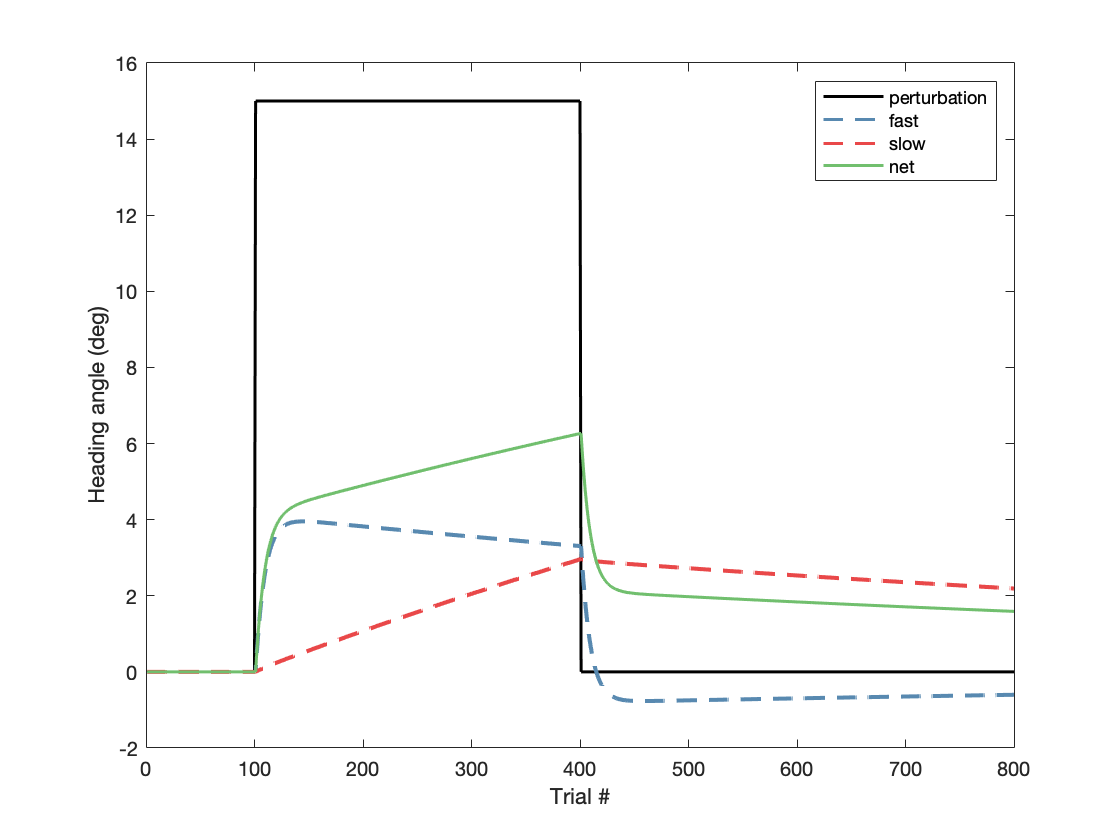

% Perturbation Schedule
schedule = nan([1 800]);
schedule(1:100) = 0; % baseline
schedule(101:400) = 15; % adaptation 
schedule(401:800) = 0; % de-adaptation 

Af = 0.92; As = 1;
Bf = 0.03; Bs = 0.001; 
[fast,slow] = twoSSM(schedule, Af, As, Bf, Bs);
net = fast+slow; 

% visualize 
cc = linspecer(3);
figure();
plot(1:800, schedule, 'k-', 'linewidth', 1.5, 'displayname', 'perturbation');
hold on 
plot(1:800, fast, '--', 'color', cc(1,:), 'linewidth', 1.5, 'displayname', 'fast');
plot(1:800, slow, '--', 'color', cc(2,:), 'linewidth', 1.5, 'DisplayName', 'slow');
plot(1:800, net, '-', 'color', cc(3,:), 'linewidth', 1.5, 'DisplayName', 'net');
xlabel('Trial #'); ylabel('Heading angle (deg)');
legend('location', 'best')

## Simulate expeirment

rotationD = 15; % degrees 
T1 = [0 0]; T2 = [0 10]; % targets 

reaching = net + rnd_btw(-1, 1, size(net));  

% visualize 
figure('visible', 'on', 'position', [400 400 800 400]);
% behavior 
subplot(1,2,1); 
plot(T1(1), T1(2), 'go', 'markersize', 10, 'linewidth', 2, 'DisplayName', 'T1');
hold on 
plot(T2(1), T2(2), 'mo', 'markersize', 10, 'linewidth', 2, 'DisplayName', 'T2');
plot(T1(1), T1(2), 'o', 'color', [.7 .7 .7], 'markerfacecolor', [.7 .7 .7], 'markersize', 8, 'linewidth', 2, 'displayname', 'hand');
plot(T1(1), T1(2), 'wo','markerfacecolor', 'w', 'markersize', 8, 'linewidth', 2, 'DisplayName', 'cursor');
axis padded
ax1 = gca; 
set(ax1, 'ylim', [-2 17])
kBackground(ax1);
xlabel('X (cm)'); ylabel('Y (cm)');
% paper figure 
subplot(1,2,2); 
plot(1:800, schedule, 'k-', 'linewidth', 1.5, 'displayname', 'perturbation');
hold on 
plot(1:800, fast, '--', 'color', cc(1,:), 'linewidth', 1.5, 'displayname', 'fast');
plot(1:800, slow, '--', 'color', cc(2,:), 'linewidth', 1.5, 'DisplayName', 'slow');
plot(1:800, net, '-', 'color', cc(3,:), 'linewidth', 1.5, 'DisplayName', 'net');
plot(1:800, reaching, 'o', 'color', cc(3,:), 'markersize', 7, 'displayname', 'reaches')
xlabel('Trial #'); ylabel('Heading angle (deg)');
legend('location', 'best')
ax2 = gca;
% simulate reaches 
x_reach = @(radius, theta, originX) radius * cosd(theta) + originX; 
y_reach = @(radius, theta, originY) radius * sind(theta) + originY; 
x_rot = @(x,y,rot) x * cosd(rot) - y * sind(rot); 
y_rot = @(x,y,rot) x * sind(rot) + y * cosd(rot); 
for t = 1:20:length(reaching)
    
    % highlight dot on experiment figure 
    plot(ax2, t, reaching(t), 'go', 'markerfacecolor', 'r', 'displayname', 'tn');
    
    % reach with bell shaped velocity 
    [reachXR, reachYR] = T1reachT2(T1, [x_reach(0, reaching(t), T1(1)) y_reach(15, reaching(t), T1(2))], 500); 
    for i = 1:15:length(reachXR)
        % hand 
        set(ax1.Children(2), 'xdata', reachXR(i));
        set(ax1.Children(2), 'ydata', reachYR(i));
        if t >= 101 && t <= 400
            % cursor 
            set(ax1.Children(1), 'xdata', x_rot(reachXR(i), reachYR(i), rotationD));
            set(ax1.Children(1), 'ydata', y_rot(reachXR(i), reachYR(i), rotationD)); 
        else
            % cursor 
            set(ax1.Children(1), 'xdata', reachXR(i));
            set(ax1.Children(1), 'ydata', reachYR(i)); 
        end
        pause(0.001); 
    end
    pause(0.01)
    % reach back 
    for i = length(reachXR):-15:1
        % hand 
        set(ax1.Children(2), 'xdata', reachXR(i));
        set(ax1.Children(2), 'ydata', reachYR(i));
        % cursor 
        if t >= 101 && t <= 400
            % cursor 
            set(ax1.Children(1), 'xdata', x_rot(reachXR(i), reachYR(i), rotationD));
            set(ax1.Children(1), 'ydata', y_rot(reachXR(i), reachYR(i), rotationD)); 
        else
            % cursor 
            set(ax1.Children(1), 'xdata', reachXR(i));
            set(ax1.Children(1), 'ydata', reachYR(i)); 
        end
        pause(0.001); 
    end
    
    % delete hilighted 
    delete(ax2.Children(1)); 
end

function [fast, slow] = twoSSM(schedule, Af, As, Bf, Bs)
% INPUTS: 
% schedule: perturbation schedule 
% Af, Bf, As, Bs: parameters 

% OUTPUTS:
% adaptVec: adaptation vector 

% ICs
x_1 = 0;
x_2 = 0;
net = 0;

fast = zeros(size(schedule));
slow = zeros(size(schedule));

for i = 1:length(schedule)-1
    % error 
    er = schedule(i) - net;
    % fast 
    fast(i+1) = Af * x_1 + Bf * er;
    % slow 
    slow(i+1) = As * x_2 + Bs * er;
    % net 
    net = fast(i+1) + slow(i+1);
    % update
    x_1 = fast(i+1);
    x_2 = slow(i+1); 
end

end